# Fingerprinting 

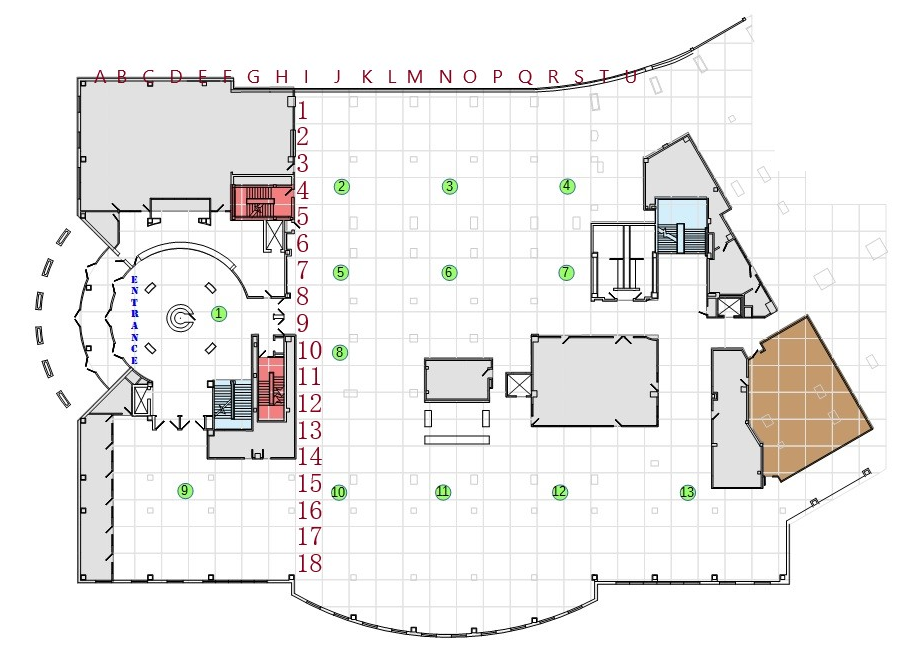

clc; clear;
cd('C:\Users\LEE SANG GU\MATLAB Drive\lab\FingerPrinting Ex\BLE_RSSI_dataset\RSSI_dataset')
data = readtable('iBeacon_RSSI_Labeled.csv');

reference_point = table2array(data(:,1));
ap_location = {'E09','D15','J04','J07','J10','J15','N04','N07','N15','R04','R07','R15','W15'};

for i = 1:size(ap_location,2)
    [ax(i,1),ay(i,1)]=to_xy(ap_location{i});
end
ap_location = [ax , ay];

reference_rss = table2array(data(:,3:end));

for i =1:size(reference_point,1)
   [x(i,1),y(i,1)] =to_xy (reference_point{i,1} );
end
dataset = [x, y, reference_rss];
dataset(find(dataset(:) ==-200)) = -150;

unique_rp = unique(dataset(:,1:2),'rows')

unique_rp =      4     4
     4     5
     4     6
     5     4
     6    11
     7     4
     9     4
     9     9
     9    10
     9    11



for i = 1:size(unique_rp,1)
rp_nsample(i,1) = size(find(ismember(dataset(:,1:2),unique_rp(i,:),'rows')),1);
end

rp_nsample

rp_nsample =     14
     4
     6
     4
     4
     4
     5
    14
     8
    26


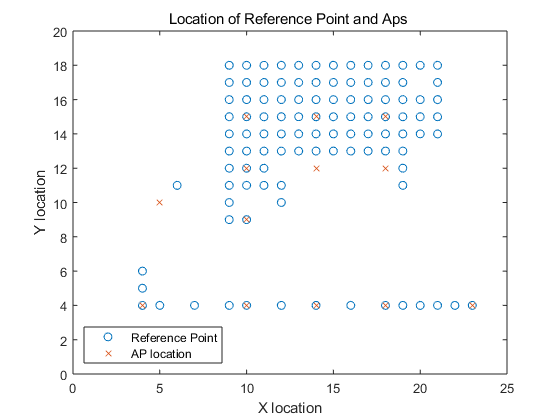


% Divide the data to validation_set and train_set 

for i = 1: size(unique_rp,1)
pool=find(ismember(dataset(:,1:2),unique_rp(i,:),'rows'));
idx = randperm(length(pool),1);
val_set(i,:)=dataset(pool(idx),:);
dataset(pool(idx),:) = [];
end
test_set = dataset;


plot(test_set(:,1),test_set(:,2),'o'); xlabel('X location'); ylabel('Y location');
xlim([0 25]); ylim([0 20]);
hold on;
plot(ap_location(:,1),ap_location(:,2),'x');
title('Location of Reference Point and Aps '); 
legend({'Reference Point' , 'AP location'},'Location','southwest');
hold off;

for i = 1:size(unique_rp,1)
radio_map(i,:) = mean(test_set(find(ismember(test_set(:,1:2),unique_rp(i,:),'rows')),:));
end
radio_map

radio_map =     4.0000    4.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000  -62.7692 -150.0000 -150.0000 -150.0000 -150.0000
    4.0000    5.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000  -68.6667 -150.0000 -150.0000 -150.0000 -150.0000
    4.0000    6.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000  -78.2000 -150.0000 -150.0000 -150.0000 -150.0000
    5.0000    4.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000  -75.3333 -150.0000 -150.0000 -150.0000 -150.0000
    6.0000   11.0000  -69.3333 -166.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000
    7.0000    4.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000  -78.6667 -150.0000 -150.0000 -150.0000
    9.0000    4.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -150.0000 -

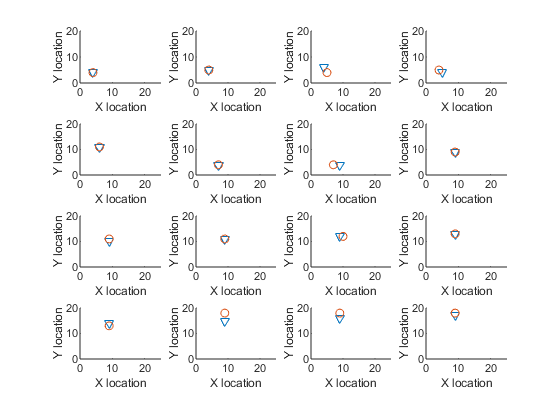

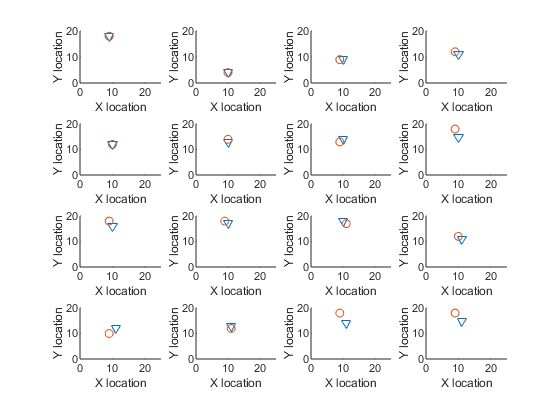

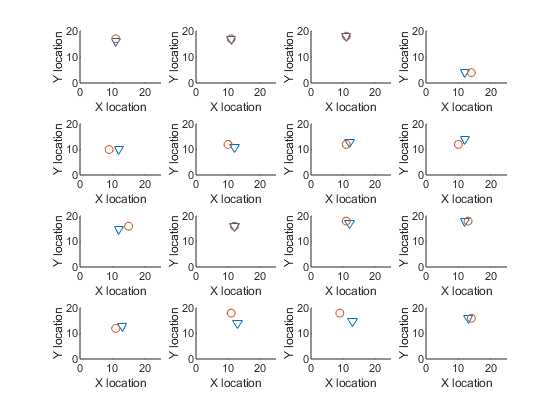

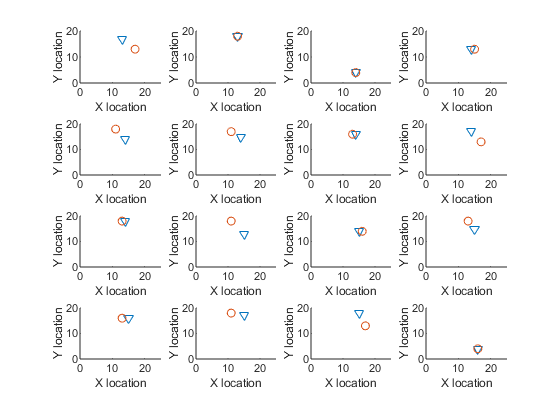

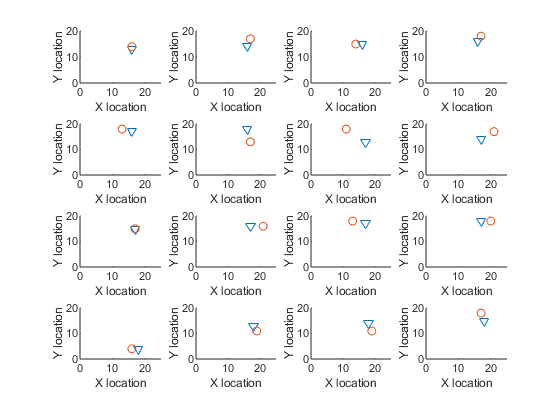

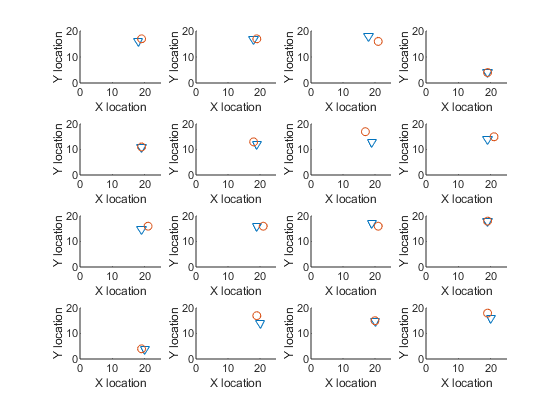

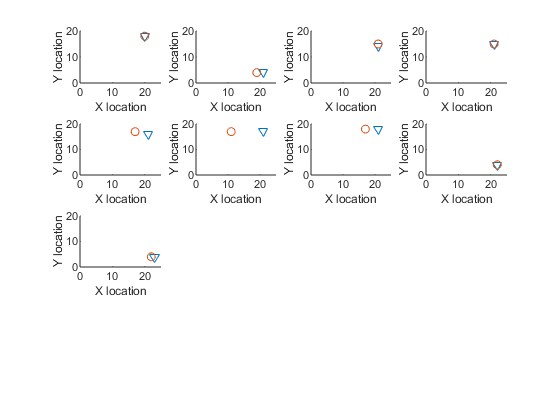

% Checking for Accuracy
total_prediction = 0;
for i = 1:size(val_set,1)
if(mod(i,16) ==1)
    figure(i);
end

predict = locate_rp(val_set(i,3:end),radio_map);
subplot(4,4,mod(i-1,16)+1);
hold on;
plot(val_set(i,1),val_set(i,2),'V'); 
plot(predict(2), predict(3),'O');
xlim([0 25]); ylim([0 20]); xlabel('X location'); ylabel('Y location');
hold off;

if((val_set(i,1) == predict(2)) && val_set(i,2) ==predict(3))
total_prediction = total_prediction + 1;
end

end

fprintf("accuracy is %f %%\n\n ", total_prediction/size(val_set,1) * 100);

accuracy is 22.857143 %

 

function [x,y] = to_xy( str )
xmap = ['A','B','C','D','E','F','G','H','I','J','K','L','M','N','O','P','Q','R','S','T','U','V','W','X','Y','Z'];
ymap = ["18","17","16","15","14","13","12","11","10","09","08","07","06","05","04","03","02","01"];
x=find(xmap == str(1));
y=find(ymap == str(2:3));
end


function e = mean_sq_err(t_val, database)

for i = 1:size(database,1)
    error(i,1) = sum((database(i,3:end) - t_val).^2) ;
end
e  = [error database(:,1:2)];

end

function rp =locate_rp(t_val,database)
e = mean_sq_err(t_val,database);

[min_val, index] = min(e(:,1));
rp = e(index,:);
end


